# For Healthy Individual

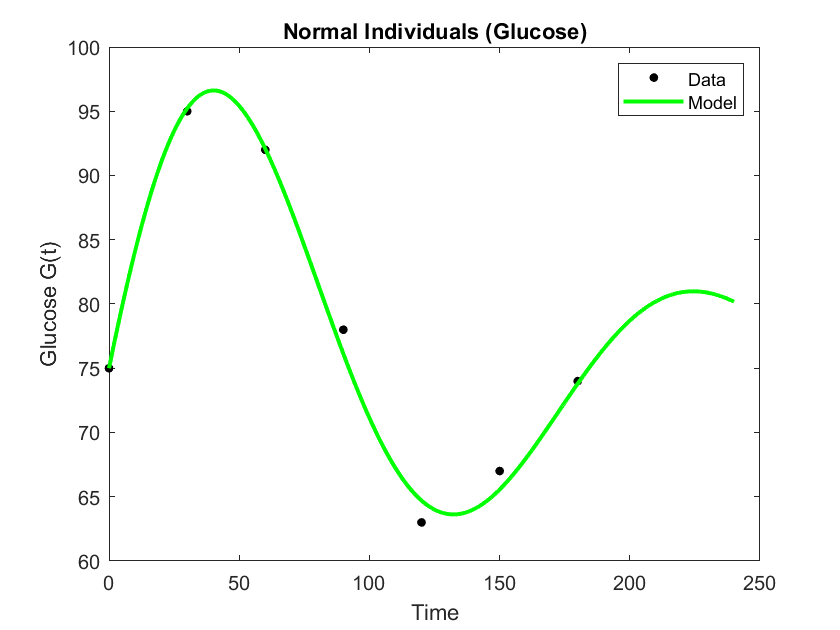

clc;
clear;
close all;

time = 0:0.1:240;
t_norm = [0, 30, 60, 90, 120, 150, 180];
G_norm = [75, 95, 92, 78, 63, 67, 74];

param_guess = [80, 0.02, 0.004]; 
[bestparam_GH, min_G] = fminsearch(@meritGH,param_guess,[], t_norm, G_norm);
yfit_GH = funGH(bestparam_GH,time);
plot(t_norm, G_norm, '.k', 'MarkerSize',15);
hold on
plot(time,yfit_GH,'g', 'LineWidth', 2);
figure(gcf);
title('Normal Individuals (Glucose)')
ylabel('Glucose G(t)'); xlabel('Time');
legend('Data','Model')
hold off

F = bestparam_GH(1)

F = 0.9956

alpha = bestparam_GH(2)

alpha = 0.0070

omega = bestparam_GH(3)

omega = 0.0341

# For Diabetic Individual

### Data

t_diab = [0, 30, 60, 120, 180, 240]; % Time vector for G
G_diab = [85,160,196,130,85,60]; % G vector
H_diab = [20, 60,132, 200, 76, 30]; % H vector

% Given G0
% diabetic
G0=85.0;

% Data for H
H_diab = [20, 60,132, 200, 76, 30]; % H vector

% diabetic initial value for insulin H0
H0=20.0;


## Glucose

G0=85.0;
% Initial guess for the parameters [F, alpha, omega]
param_guess=[80, 0.002, 0.004]; % F, alpha, omega

[bestparam_G, min_G] = fminsearch(@meritG,param_guess,[], t_diab, G_diab);
yfit_G = funG(bestparam_G,time);
plot(t_diab, G_diab, '.k', 'MarkerSize',15);
hold on
plot(time,yfit_G,'b', 'LineWidth', 2);
figure(gcf);
title('Diabetic Individuals (Glucose)')
ylabel('Glucose G(t)'); xlabel('Time');
legend('Data','Model')
%hold off
F = bestparam_G(1)

F = 3.7396

alpha = bestparam_G(2)

alpha = 0.0094

omega = bestparam_G(3)

omega = 0.0185

A = F/omega

A = 202.5509

## Insulin

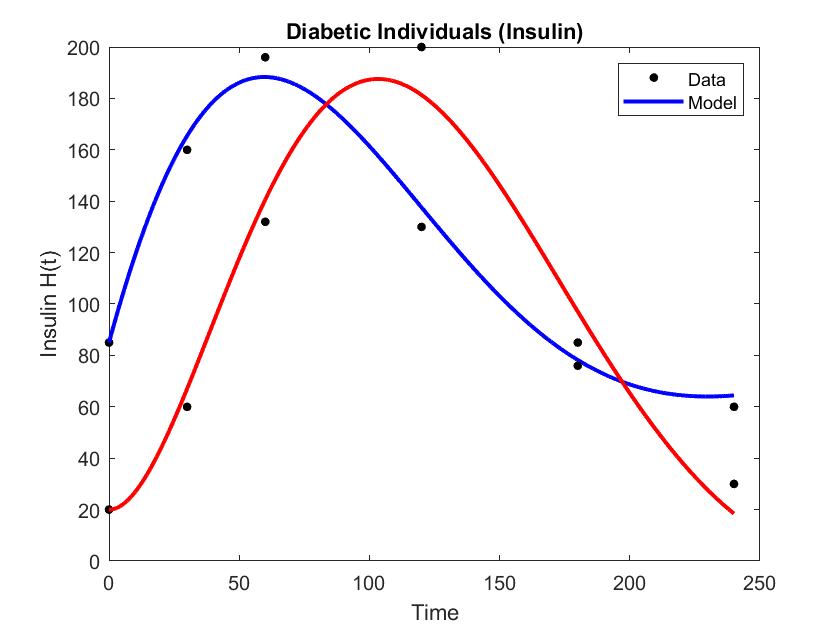

param_guess_H=[0.01, 0.04]; % initial guess for c, d

options = optimset('TolFun', 1e-6, 'TolX', 1e-6);
[bestparam_H, min_H] = fminsearch(@meritH,param_guess_H,options, t_diab, H_diab, F, alpha, omega);
yfit_H = funH(bestparam_H,time, F, alpha, omega);
plot(t_diab, H_diab, '.k', 'MarkerSize',15);
hold on
plot(time,yfit_H,'r', 'LineWidth', 2);
figure(gcf);
title('Diabetic Individuals (Insulin)')
ylabel('Insulin H(t)'); xlabel('Time');
legend('Data','Model')
hold off

c = bestparam_H(1)

c = 0.0179

d = bestparam_H(2)

d = 0.0414

### Finding Variables

a = 2*alpha - c

a = 8.0345e-04

disp(['a: ', num2str(a)]);

a: 0.00080345


b = (omega^2 + alpha^2 - (a*c))/d

b = 0.0100

A = F/omega

A = 202.5509

omega_0 = sqrt(omega^2 + alpha^2)

omega_0 = 0.0207

period_G = (2*pi)/omega_0

period_G = 303.5078

# Extended Diabetic Prediction Model

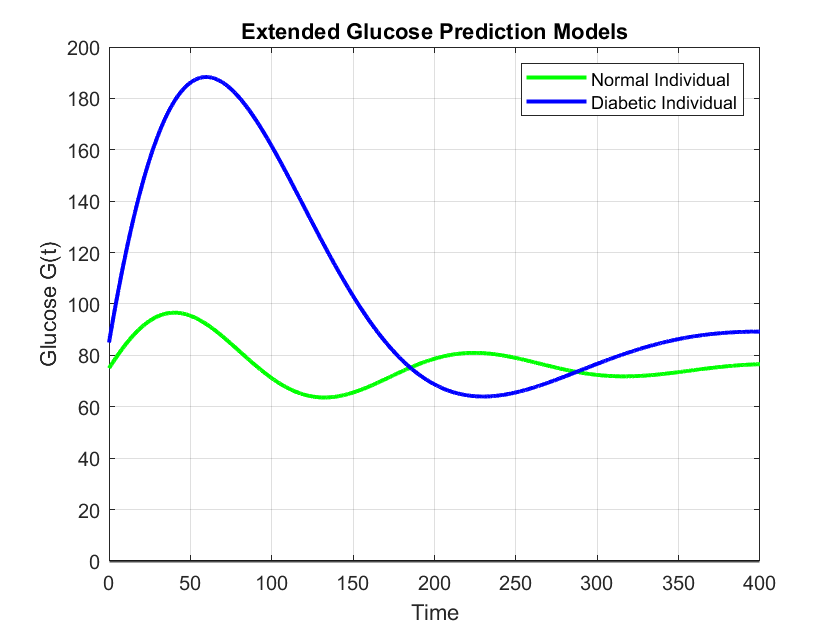

t_lng = 0:0.1:400;
G_N = funGH(bestparam_GH,t_lng);
G_D = funG(bestparam_G,t_lng);
plot(t_lng,G_N,'g', 'LineWidth', 2);
hold on
plot(t_lng,G_D,'b', 'LineWidth', 2);
figure(gcf);
grid on
yline(0, 'Color', 'k', 'LineWidth', 1);
title('Extended Glucose Prediction Models')
ylabel('Glucose G(t)'); xlabel('Time');
legend('Normal Individual','Diabetic Individual')
hold off

# Injection Treatment

%I0 and K0 are delta functions
syms s t G H
I0 = 75;
K0 = 35;

*Varied Treatment*

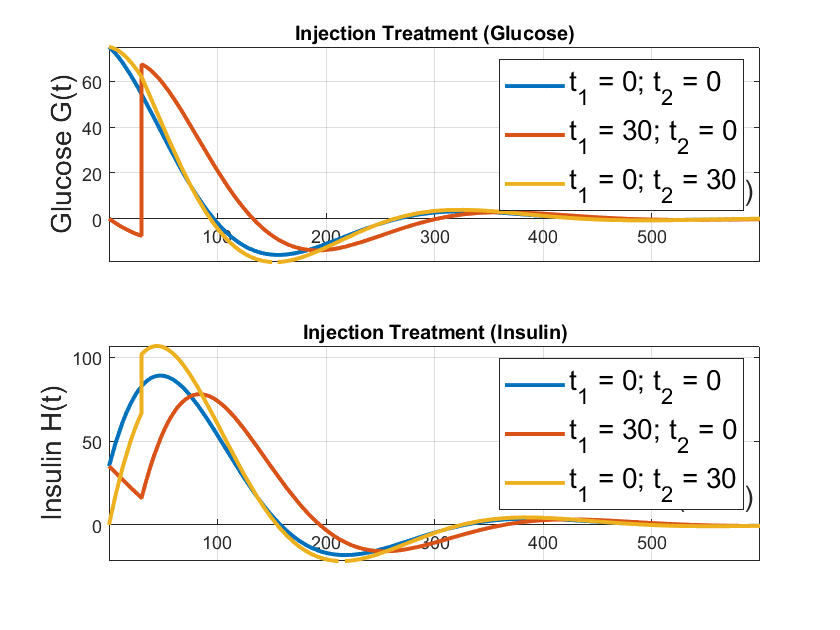

time_sets = {[0,0],[30,0], [0,30]};

varied = figure;
glucose_subplot_varied = subplot(2,1,1);
insulin_subplot_varied = subplot(2,1,2);

for interval = time_sets
    t1 = interval{1}(1);
    t2 = interval{1}(2);
    G = -b*K0*exp(-s*t2)/((s+alpha)^2+omega^2) + I0*(s+c)*exp(-s*t1)/((s+alpha)^2+omega^2);
    solG = ilaplace(G,s,t);
    subplot(glucose_subplot_varied)
    fplot(solG,[0,600], 'LineWidth', 2);
    hold on
end
grid on
ax1 = gca;
ax1.XAxisLocation = 'origin';
ax1.YAxisLocation = 'origin';
title('Injection Treatment (Glucose)')
ylabel('Glucose G(t)', 'fontsize', 14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('t_1 = 0; t_2 = 0', 't_1 = 30; t_2 = 0', 't_1 = 0; t_2 = 30','fontsize', 14);

for interval = time_sets
    t1 = interval{1}(1);
    t2 = interval{1}(2);
    G = -b*K0*exp(-s*t2)/((s+alpha)^2+omega^2) + I0*(s+c)*exp(-s*t1)/((s+alpha)^2+omega^2);
    H = d*G/(s+c) + K0*exp(-s*t2)/(s+c);
    solH = ilaplace(H,s,t);
    subplot(insulin_subplot_varied)
    fplot(solH,[0,600],'LineWidth', 2);
    hold on
end
grid on
ax2 = gca;
ax2.XAxisLocation = 'origin';
ax2.YAxisLocation = 'origin';
title('Injection Treatment (Insulin)')
ylabel('Insulin H(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('t_1 = 0; t_2 = 0', 't_1 = 30; t_2 = 0', 't_1 = 0; t_2 = 30','fontsize', 14);

*Late Treatment*

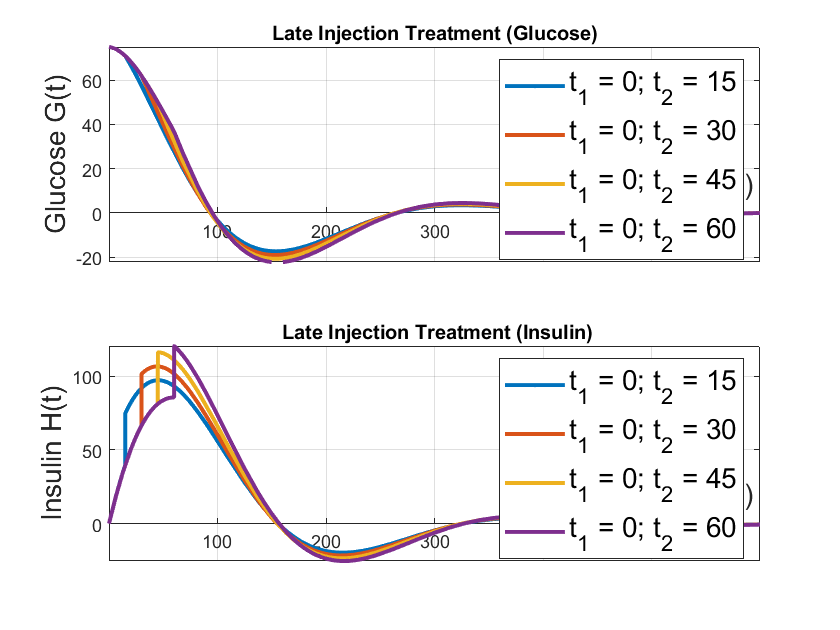

time_sets_2 = {[0,15], [0,30], [0,45], [0,60]};

Late = figure;
glucose_subplot_late = subplot(2,1,1);
insulin_subplot_late = subplot(2,1,2);

for interval = time_sets_2
    t1 = interval{1}(1);
    t2 = interval{1}(2);
    G = -b*K0*exp(-s*t2)/((s+alpha)^2+omega^2) + I0*(s+c)*exp(-s*t1)/((s+alpha)^2+omega^2);
    solG = ilaplace(G,s,t);
    subplot(glucose_subplot_late)
    fplot(solG,[0,600], 'LineWidth', 2);
    hold on
end
grid on
ax3 = gca;
ax3.XAxisLocation = 'origin';
ax3.YAxisLocation = 'origin';
title('Late Injection Treatment (Glucose)')
ylabel('Glucose G(t)', 'fontsize', 14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('t_1 = 0; t_2 = 15', 't_1 = 0; t_2 = 30', 't_1 = 0; t_2 = 45', 't_1 = 0; t_2 = 60','fontsize', 14)

for interval = time_sets_2
    t1 = interval{1}(1);
    t2 = interval{1}(2);
    G = -b*K0*exp(-s*t2)/((s+alpha)^2+omega^2) + I0*(s+c)*exp(-s*t1)/((s+alpha)^2+omega^2);
    H = d*G/(s+c) + K0*exp(-s*t2)/(s+c);
    solH = ilaplace(H,s,t);
    subplot(insulin_subplot_late)
    fplot(solH,[0,600],'LineWidth', 2);
    hold on
end
grid on
ax4 = gca;
ax4.XAxisLocation = 'origin';
ax4.YAxisLocation = 'origin';
title(' Late Injection Treatment (Insulin)')
ylabel('Insulin H(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('t_1 = 0; t_2 = 15', 't_1 = 0; t_2 = 30', 't_1 = 0; t_2 = 45', 't_1 = 0; t_2 = 60','fontsize', 14)

*Early Treatment*

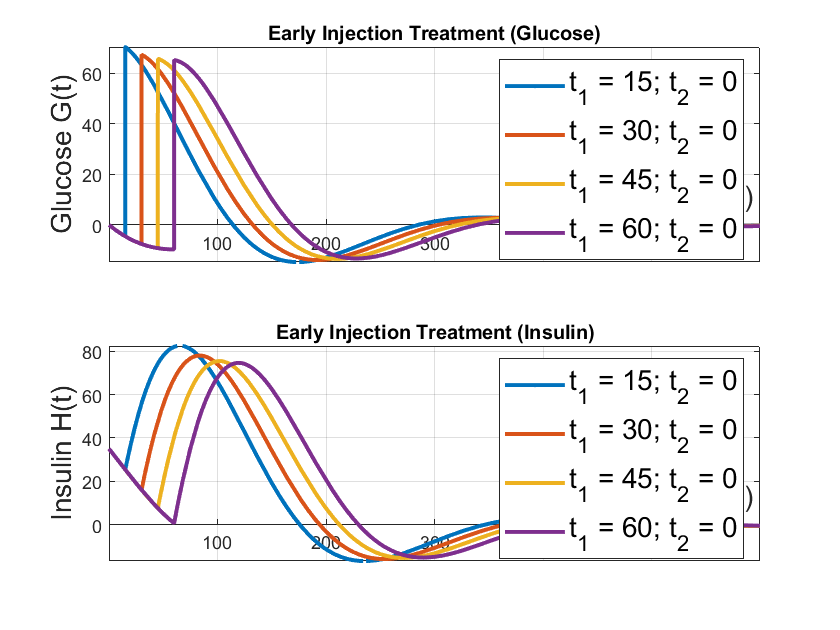

time_sets_3 = {[15,0], [30,0], [45,0], [60,0]};

Early = figure;
glucose_subplot_early = subplot(2,1,1);
insulin_subplot_early = subplot(2,1,2);

for interval = time_sets_3
    t1 = interval{1}(1);
    t2 = interval{1}(2);
    G = -b*K0*exp(-s*t2)/((s+alpha)^2+omega^2) + I0*(s+c)*exp(-s*t1)/((s+alpha)^2+omega^2);
    solG = ilaplace(G,s,t);
    subplot(glucose_subplot_early)
    fplot(solG,[0,600], 'LineWidth', 2);
    hold on
end
grid on
ax5 = gca;
ax5.XAxisLocation = 'origin';
ax5.YAxisLocation = 'origin';
title('Early Injection Treatment (Glucose)')
ylabel('Glucose G(t)', 'fontsize', 14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('t_1 = 15; t_2 = 0', 't_1 = 30; t_2 = 0', 't_1 = 45; t_2 = 0', 't_1 = 60; t_2 = 0','fontsize', 14)

for interval = time_sets_3
    t1 = interval{1}(1);
    t2 = interval{1}(2);
    G = -b*K0*exp(-s*t2)/((s+alpha)^2+omega^2) + I0*(s+c)*exp(-s*t1)/((s+alpha)^2+omega^2);
    H = d*G/(s+c) + K0*exp(-s*t2)/(s+c);
    solH = ilaplace(H,s,t);
    subplot(insulin_subplot_early)
    fplot(solH,[0,600],'LineWidth', 2);
    hold on
end
grid on
ax6 = gca;
ax6.XAxisLocation = 'origin';
ax6.YAxisLocation = 'origin';
title('Early Injection Treatment (Insulin)')
ylabel('Insulin H(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('t_1 = 15; t_2 = 0', 't_1 = 30; t_2 = 0', 't_1 = 45; t_2 = 0', 't_1 = 60; t_2 = 0','fontsize', 14)
hold off

# Step Functions

*Insulin First*

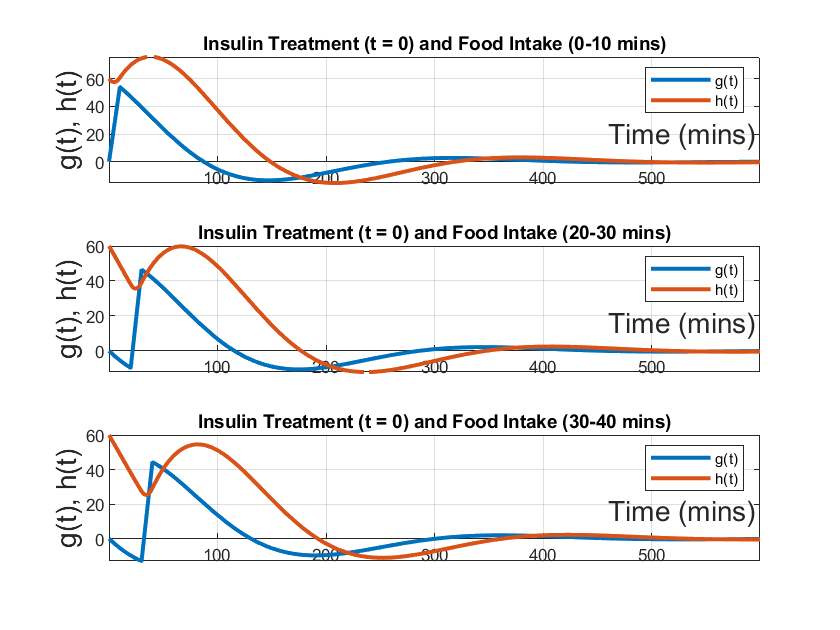

%I(t) is step-function, K(t) is delta-function
syms s t G H
K0=60; %test with 30 and 40
I0=6.0;
t0 = 0; %time for K(t) (insulin treatment)

tau1 = 0;
tau2 = 10;
G = -b*K0*exp(-s*t0)/((s+alpha)^2+omega^2)+I0*(s+c)*(exp(-s*tau1)-exp(-s*tau2))/(s*((s+alpha)^2+omega^2));
H = d*G/(s + c) + K0*exp(-s*t0)/(s + c);
solG = ilaplace(G,s,t);
solH = ilaplace(H,s,t);
figure;
subplot(3,1,1);
fplot(solG,[0,600], 'LineWidth', 2);
hold on
fplot(solH,[0,600],'LineWidth', 2);
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title('Insulin Treatment (t = 0) and Food Intake (0-10 mins)')
ylabel('g(t), h(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('g(t)','h(t)')

tau1 = 20;
tau2 = 30;
G = -b*K0*exp(-s*t0)/((s+alpha)^2+omega^2)+I0*(s+c)*(exp(-s*tau1)-exp(-s*tau2))/(s*((s+alpha)^2+omega^2));
H = d*G/(s + c) + K0*exp(-s*t0)/(s + c);
solG = ilaplace(G,s,t);
solH = ilaplace(H,s,t);
subplot(3,1,2);
fplot(solG,[0,600], 'LineWidth', 2);
hold on
fplot(solH,[0,600],'LineWidth', 2);
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title('Insulin Treatment (t = 0) and Food Intake (20-30 mins)')
ylabel('g(t), h(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('g(t)','h(t)')

tau1 = 30;
tau2 = 40;
G = -b*K0*exp(-s*t0)/((s+alpha)^2+omega^2)+I0*(s+c)*(exp(-s*tau1)-exp(-s*tau2))/(s*((s+alpha)^2+omega^2));
H = d*G/(s + c) + K0*exp(-s*t0)/(s + c);
solG = ilaplace(G,s,t);
solH = ilaplace(H,s,t);
subplot(3,1,3);
fplot(solG,[0,600], 'LineWidth', 2);
hold on
fplot(solH,[0,600],'LineWidth', 2);
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title('Insulin Treatment (t = 0) and Food Intake (30-40 mins)')
ylabel('g(t), h(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('g(t)','h(t)')

*Both Step Functions*

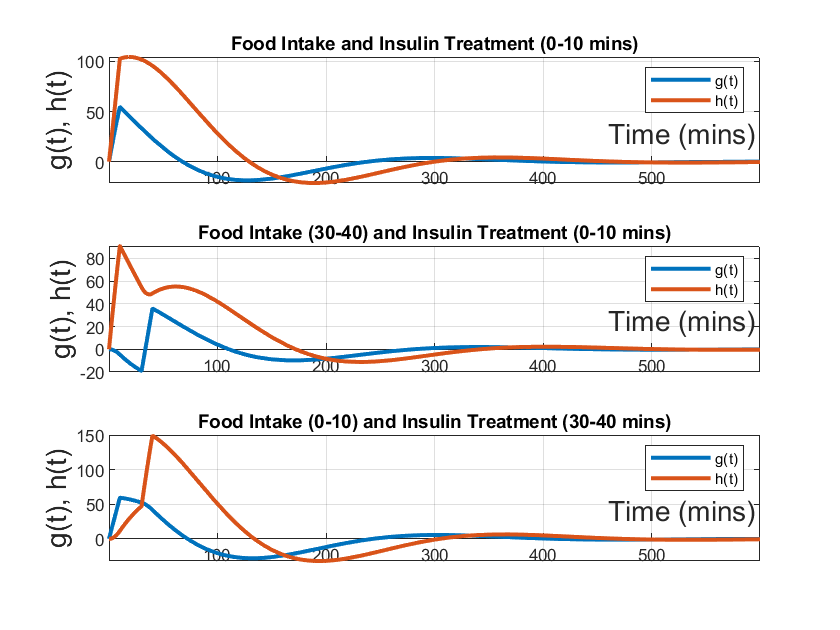

%I(t) is step-function, K(t) is step-function
syms s t G H
K0=10;
I0=6.0;

tau1 = 0; %food intake
tau2 = 10;
lambda1 = 0; %insulin treatment
lambda2 = 10;
G = -b*K0*(exp(-lambda1*s)/s - exp(-lambda2*s)/s)/((s+alpha)^2+omega^2)+I0*(s+c)*(exp(-s*tau1)-exp(-s*tau2))/(s*((s+alpha)^2+omega^2));
H = d*G/(s + c) + K0*(exp(-lambda1*s) - exp(-lambda2*s))/((s + c)*s);
solG = ilaplace(G,s,t);
solH = ilaplace(H,s,t);
figure;
subplot(3,1,1);
fplot(solG,[0,600], 'LineWidth', 2);
hold on
fplot(solH,[0,600],'LineWidth', 2);
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title('Food Intake and Insulin Treatment (0-10 mins)')
ylabel('g(t), h(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('g(t)','h(t)')

tau1 = 30; %food intake
tau2 = 40;
lambda1 = 0; %insulin treatment
lambda2 = 10;
G = -b*K0*(exp(-lambda1*s)/s - exp(-lambda2*s)/s)/((s+alpha)^2+omega^2)+I0*(s+c)*(exp(-s*tau1)-exp(-s*tau2))/(s*((s+alpha)^2+omega^2));
H = d*G/(s + c) + K0*(exp(-lambda1*s) - exp(-lambda2*s))/((s + c)*s);
solG = ilaplace(G,s,t);
solH = ilaplace(H,s,t);
subplot(3,1,2);
fplot(solG,[0,600], 'LineWidth', 2);
hold on
fplot(solH,[0,600],'LineWidth', 2);
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title('Food Intake (30-40) and Insulin Treatment (0-10 mins)')
ylabel('g(t), h(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('g(t)','h(t)')

tau1 = 0; %food intake
tau2 = 10;
lambda1 = 30; %insulin treatment
lambda2 = 40;
G = -b*K0*(exp(-lambda1*s)/s - exp(-lambda2*s)/s)/((s+alpha)^2+omega^2)+I0*(s+c)*(exp(-s*tau1)-exp(-s*tau2))/(s*((s+alpha)^2+omega^2));
H = d*G/(s + c) + K0*(exp(-lambda1*s) - exp(-lambda2*s))/((s + c)*s);
solG = ilaplace(G,s,t);
solH = ilaplace(H,s,t);
subplot(3,1,3);
fplot(solG,[0,600], 'LineWidth', 2);
hold on
fplot(solH,[0,600],'LineWidth', 2);
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title('Food Intake (0-10) and Insulin Treatment (30-40 mins)')
ylabel('g(t), h(t)', 'FontSize',14); 
xlabel('Time (mins)', 'fontsize', 14);
legend('g(t)','h(t)')

### Functions

function sumsquares=meritGH(param, t,G)
 DIFF = funGH(param,t) - G;
 SQ_DIFF = DIFF.^2;
 sumsquares = sum(SQ_DIFF);
end
 
function Y=funGH(coeff,t)
 F = coeff(1);
 alpha = coeff(2);
 omega = coeff(3);
 Y= 75 + (F./omega).*exp(-alpha.*t).*sin(omega*t);
end

function sumsquares=meritG(param, t,G)
 DIFF = funG(param,t)-G;
 SQ_DIFF = DIFF.^2;
 sumsquares = sum(SQ_DIFF);
end
 
function Y=funG(coeff,t)
 F = coeff(1);
 alpha = coeff(2);
 omega = coeff(3);
 Y= 85 + (F./omega).*exp(-alpha.*t).*sin(omega*t);
end


function sumsquares = meritH(param, t, G, F, alpha, omega)
 DIFF = funH(param,t, F, alpha, omega) - G;
 SQ_DIFF = DIFF.^2;
 sumsquares = sum(SQ_DIFF);
end

function Y_H = funH(coeff,t, F, alpha, omega)
 c = coeff(1);
 d = coeff(2);
 Y_H= 20 + ((F*d)/(omega.*((c-alpha).^2 + omega.^2))).*(omega.*(exp(-c.*t) - exp(-alpha.*t).*cos(omega.*t)) + (c-alpha).*exp(-alpha.*t).*sin(omega.*t));
end